# 线性规划linprog函数求解

## linprog函数求解线性规划模型

linprog函数中的变量必须是**matlab标准型**

函数`：[x,fval]= linprog(f,A,b,Aeq,beq,lb,ub)`

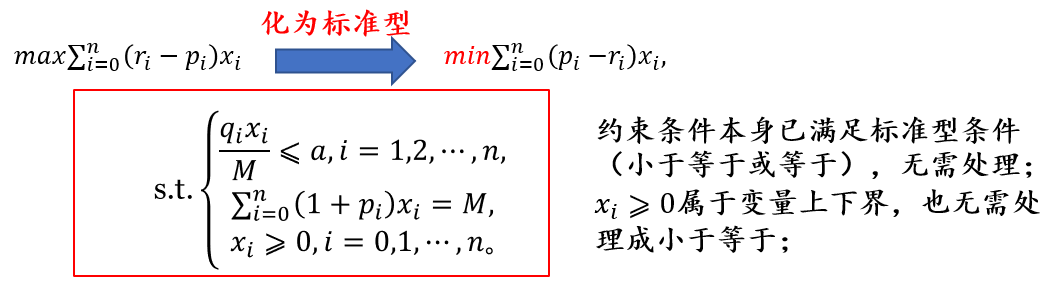

% clc是清除命令行窗口，clear是清除存储空间的变量
clc,clear;
% a矩阵的元素是不同风险率，从0到0.05等差取值，相邻两个数相差0.001
a = (0:0.001:0.05);     
f = [-0.05,-0.27,-0.19,-0.185,-0.185];      % 目标函数的系数向量
% A是不等式约束条件的变量系数构成的矩阵
% 用zeros(4,1)先构造4行一列的全是0的矩阵，也就是对x_0无约束；
% 再构造对角矩阵diag([0.025,0.015,0.055,0.026])，对角线上元素为约束条件中变量的系数
A = [zeros(4,1),diag([0.025,0.015,0.055,0.026])];   
Aeq = [1,1.01,1.02,1.045,1.065];        % 等式约束的系数矩阵，也就是所有资产投资
beq = 1;
LB = zeros(5,1);
Q = zeros(1,length(a));     % 初始化保存最优解的矩阵Q，因为现在还没求出最优解，元素全设为0
XX = [];    % 定义个空矩阵，用来存不同风险率下的最优解
% 利用矩阵Q存储风险率a(i)下最大的收益；for循环中i在变化，风险率a(i)不同，求出对应的最优解存在矩阵Q内
for i = 1:length(a)         % length求出矩阵a的元素个数，有多少个元素，就循环多少次  
    b = a(i)*ones(4,1);     % b是约束条件的常数项矩阵,4行1列，每个元素值都是常数a(i)
    [x,y] = linprog(f,A,b,Aeq,beq,LB);      % 调用linprog函数
    Q(i) = -y;      % 负负得正，就是所需求的最大值了
    XX = [XX;x'];
end

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solu

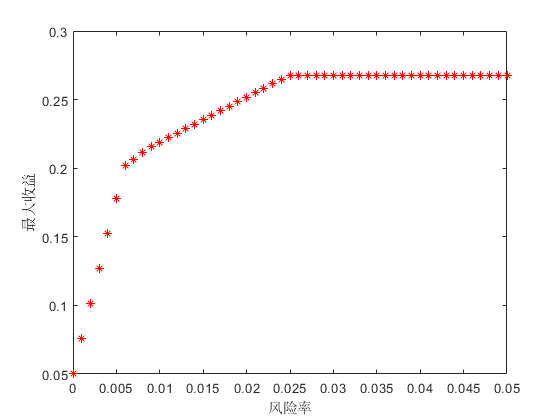

plot(a,Q,'*r');      % 以风险率为横轴，收益为纵轴，绘制不同风险率下的最优收益
xlabel('风险率');        % x和y轴分别附上标签
ylabel('最大收益');

## 注意事项

linprog函数的标准形式是[x, fval ]= linprog(f,A,b,Aeq,beq,lb,ub)

- 若不存在不等式约束，用“ [ ]” 代替𝐴和𝑏： [𝑥, fval ]= linprog (𝑓,[ ],[ ],𝐴𝑒𝑞, beq ,𝑙𝑏,𝑢𝑏)

- 若不存在等式约束，用“ [ ]” 代替𝐴𝑒𝑞和𝑏𝑒𝑞： [𝑥, fval ]= linprog (𝑓,𝐴,𝑏,[ ], [ ] ,𝑙𝑏,𝑢𝑏)

- 没有等式约束和最小、最大取值的约束时，可以不写𝐴𝑒𝑞,𝑏𝑒𝑞 和𝑙𝑏,𝑢𝑏： [𝑥, fval ]= linprog (𝑓,𝐴,𝑏)

- 若题目求最大值：目标函数等号两端加负号转为求最小值，求解后目标值再取负

## 运行结果

矩阵a中有51个元素，代表51个风险率的取值；

矩阵Q中有51个元素，是在不同风险率之下对应求得的最大收益；

以a中元素为横坐标，Q中元素为纵坐标，得图如下：

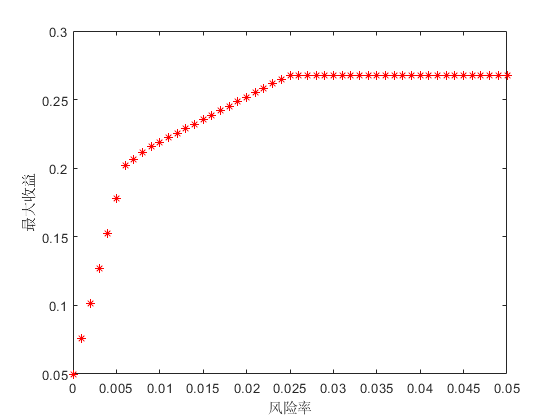

%本文件出自b站/公众号：数学建模BOOM
% 关注公众号：数学建模BOOM，回复"购买"
% 获取全套视频课程+配套PPT课件+代码文件+完善售后服务+后续课程更新
% 版权所有，侵权必究。本文件仅供购买者学习使用，不得随意传播，否则为侵权行为